# Computational Physics (PHY4602) - Symbolic Mathematics

## Overview

In the old days science and engineering students were required to purchase a “standard” mathematics handbook. Today, there are very few students, if any, who own and use a mathematics handbook. The computer and tools like MATLAB have changed this situation in a positive way. We will start with algebra including linear algebra, vector algebra and matrix algebra. Then we will examine differentiation and integration. This will be followed by investigating integral transforms and, in particular, the Laplace transform. Then we will conclude by investigating the symbolic solution of differential equations.

## Symbolic Variables

The `syms` function creates a variable dynamically. For example, the command:

syms x 
syms a b c

creates a single symbolic variable `x` or multiple variables `a`, `b` and `c` at once and automatically assigns them to corresponding MATLAB variables with the same names. You can then use the variables in the workspace for symbolic workflow. 

The `assume` and `assumeAlso` functions let you state that a variable or an expression belongs to one of these sets: integers, positive numbers, rational numbers, and real numbers. To set an assumption on a symbolic variable, use the `assume` function. For example, assume that the variable `x` is nonnegative:

assume(x >= 0)

If you want to add a new assumption to the existing assumptions, use `assumeAlso`. For example:

assumeAlso(x, {'integer', 'real'})

Now the variable `x` becomes a positive real integer. 

Check the assumptions of `x`:

assumptions(x)

## Algebra

The function `solve` can be used to solve the simultaneous system of quadratic equations:


$$x^2 +3y=0,{\;\;\;\;y}^2 +2x=0$$


Typing and executing the following command will produce the results:

syms x y
[x, y] = solve(x^2 + 3*y, y^2 + 2*x)

The results indicate that $x$ and $y$ each have four roots. Two are real and two are complex. This points to the fact that MATLAB deals with complex numbers and, hence, not just real numbers. This is another important capability of MATLAB. In MATLAB by default, $i$ and $j$ represent the number $\sqrt{-1}$.

Try the function for three simultaneous linear equations: 


$$\begin{array}{l}
x+y+z=1\;\;\\
2x+3y+z=1\\
x+y+3z=0
\end{array}$$


syms x y z
[x, y, z] = solve(x + y + z == 1, 2*x + 3*y + z - 1 == 1, x + y + 3*z == 0)

### Polynomials

The quadratic equation can be written as follows: $ax^2 +\textrm{bx}+c=0$. Let us solve this equation using the solve utility in MATLAB. To do this we can execute the following script:

syms a b c x
solve(a*x^2 + b*x + c, x)

Thus, as expected, the solutions of the quadratic equation are:


$$x=-\frac{1}{2a}\left(b\pm \sqrt{b^2 -4\textrm{ac}}\right)$$


Next, let us examine the cubic polynomial: $ax^3 +{\textrm{bx}}^2 +\textrm{cx}+d=0$. To find the roots of this equation we can execute the following script:

syms a b c d x
solve(a*x^3 + b*x^2 + c*x + d, x)

Let us consider another example. Let us solve: ${\textrm{ax}}^4 +\textrm{cx}=0$. The following commands were executed to compute the solutions:

syms a c x
solve(a*x^4 + c*x, x)

### Vectors

The single row or single column arrays are vectors. Let us consider the following 3-component vectors:


$${\mathbf{x}}_1 =\left(a_1 ,\;b_1 ,c_1 \right),\;\;{\mathbf{x}}_2 =\left(a_2 ,\;b_2 ,c_2 \right)$$


There are two ways to multiply these mathematical objects that most of the students are familiar. They are the inner or dot product and the vector or cross product. They can be found by applying the following script:

syms a1 a2 b1 b2 c1 c2
x1 = [a1, b1, c1]
x2 = [a2, b2, c2]
DotProduct = dot(x1, x2)
CrossProduct = cross(x1, x2)

### STEM Spotlight 💡: Coordinate System Transformation

We know that coordinate systems like the Cartesian and spherical systems can be transformed from one to another by using transformation matrices. The following shows an equation to transform a vector from the Cartesian to spherical systems:


$$\left\lbrack \begin{array}{c}
A_r \\
A_{\theta } \\
A_{\phi } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\sin \;\theta \;\cos \;\phi  & \sin \;\theta \;\sin \;\phi  & \cos \;\theta \\
\cos \;\theta \;\cos \;\phi  & \cos \;\theta \;\sin \;\phi  & -\sin \;\theta \\
-\sin \;\phi  & \cos \;\phi  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
A_x \\
A_y \\
A_z 
\end{array}\right\rbrack$$


The equation can be written in symbolic variables as follows:

syms A_x A_y A_z theta phi A_r A_theta A_phi 
Spherical = [A_r; A_theta; A_phi] 
Cartesian = [A_x; A_y; A_z]
Cart2SpherMatrix = [sin(theta)*cos(phi), cos(theta)*sin(phi), cos(theta);...
    cos(theta)*cos(phi), cos(theta)*sin(phi), -sin(theta);...
    -sin(phi), cos(phi), 0]
Cart2SpherEqn = Spherical == Cart2SpherMatrix * Cartesian
Spher2CartEqn = Cartesian == Cart2SpherMatrix' * Spherical

Suppose we want to express a vector $\vec{B} =\frac{10}{r}{\hat{a} }_r +r\;\cos \;\theta \;{\hat{a} }_{\theta } +{\hat{a} }_{\phi }$ in Cartesian coordinate system:

syms r theta phi
B(r, theta, phi) = [10/r; r*cos(theta); 1]
BCart = Cart2SpherMatrix' * B

Then, to find $\vec{B} \left(-3,4,0\right)$, we can use the fact that the point transformation from Cartesian to spherical coordinate systems is given by:


$$\begin{array}{l}
r=\sqrt{x^2 +y^2 +z^2 }\\
\phi =\tan^{-1} \left(\frac{\sqrt{x^2 +y^2 }}{z}\right)\\
\theta =\tan^{-1} \left(\frac{y}{x}\right)
\end{array}$$


The following script perfoms point transformation and subtitution:

X = -3
Y = 4
Z = 0
R = sqrt(X^2 + Y^2 + Z^2)
Phi = atan(sqrt(X^2 + Y^2) / Z)
Theta = atan(Y / X)
BCart(R, Theta, Phi)
vpa(BCart(R, Theta, Phi))

### Matrices

Let us consider the following mathematical objects known as matrices. We can multiply, divide and perform other mathematical operations opn the two matrices:


$${\mathbf{M}}_{\mathbf{a}} =\left(\begin{array}{cc}
a_{11}  & a_{12} \\
a_{21}  & a_{22} 
\end{array}\right),\;\;{\mathbf{M}}_{\mathbf{b}} =\left(\begin{array}{cc}
b_{11}  & b_{12} \\
b_{21}  & b_{22} 
\end{array}\right)$$


syms a11 a12 a21 a22 b11 b12 b21 b22
Ma = [a11, a12; a21, a22]
Mb = [b11, b12; b21, b22]
MSum = Ma + Mb
MProduct = Ma * Mb
MaDet = det(Ma)
MaInv = inv(Ma)
MaInvMaProduct = Ma * MaInv
simplify(MaInvMaProduct)

The eigenvalues associated with the matric ${\mathbf{M}}_{\mathbf{b}}$ can be computed as follows:

[EigenVecMb, EigenValMb] = eig(Mb)

This is a result of diagonalizing the matrix (a process interpreted geometrically as a rotation of the coordinate system to find the coordinates in which the matrix only has finite diagonal terms). The coordinate system at which this occurs is given by the orthogonal eigenvectors. 

## Calculus

We will examine symbolic differentiation and integration simultaneously because they are essentially inverse operation. Let us examine the quadratic function: $f=ax^2 +\textrm{bx}+c$. The derivative of this equation is: $\frac{\textrm{df}}{\textrm{dx}}=2\textrm{ax}+b$. This can be verified by the following:

syms x a b c
f = a*x^2 + b*x + c
df = diff(f, x)
F = int(df, x)

The result obtained is f to within a constant. The integration tool does not explicitly include the arbitrary constant of integration. Hence, a constant needs to be added as illustrated:

F = F + c
F = expand(F)

Then the function with the added constant is expanded , leading to the result sought, i.e., the recovery of the original function $f$.

Let us examine a second example. It is the examination of$f=a\;\sin^2 \;x+b\;\cos \;x$. Differentiating this formula and, subsequently, integrating the derivative, is performed by the following script: 

syms x a b 
f(x) = a*sin(x)^2 + b*cos(x)
df = diff(f, x)
F = int(df, x)
F = expand(F)

Note that the result of the integration is fully in terms of cosine. To obtain the original equation, we rewrite the first cosine term in terms of sine, and subtitute it back:

F = subs(F, cos(x)^2, rewrite(cos(x)^2, 'sin'))
F = expand(F)

## Laplace and Z Transforms

In this section the useful transforms known as the Laplace and the Z transforms are introduced by way of an example. Transforms are useful in applied mathematics as applied to examine engineering and scientific problems. There are other transforms available in MATLAB that could be investigated as well. Let us examine the Laplace and the Z transforms of the function $y=\sin \;x$:

syms x t w
y = sin(x)
yLaplace = laplace(y)
yInvLaplace = ilaplace(yLaplace, x)
yZTrans = ztrans(y)
fplot(y)
hold on
fplot(yLaplace)
fplot(yInvLaplace)
fplot(yZTrans)
hold off
legend('y', 'Laplace', 'Inverse Laplace', 'Z');
xlabel('x'); ylabel('f(x)');

## Differential Equations

The function `dsolve` is an ordinary differential equation and a system of ordinary differential equation (ODE) solver. We will examine two examples in this section. One is the solution of a single ODE and a system of ODEs. Let us examine the equation:


$$\frac{d^3 y}{{\textrm{dx}}^3 }={\textrm{ax}}^2$$


To solve this equation all we need to do is to execute the following command:

syms y(x)
dsolve(diff(y, 3) == a*x^2)

Since it is a third-order differential equation, solving it requires three integrations and, hence, the result is to within three arbitrary constants.

Next, we solve two equations simultaneously with specified constraints (or boundary conditions). The equations to be solved are:


$$\frac{\textrm{df}}{\textrm{dt}}=3f+4g,\;\;\;\frac{\textrm{dg}}{\textrm{dt}}=-4f+3g$$


This system of equations, since it is second order, is subject to two constraints. In this example they are $f\left(0\right)=0$ and $g\left(0\right)=1$, which can be interpreted as initial conditions. The solution can be obtained by implementing the following command in MATLAB:

syms f(t) g(t)
Equations = [diff(f) == 3*f + 4*g, diff(g) == -4*f + 3*g];
Conditions = [f(0) == 0, g(0) == 1];
[f, g] = dsolve(Equations, Conditions)

## Physics Pinpoint 🔎: Motion of Simple Pendulum

This example simulates the motion of a simple pendulum. Derive the equation of motion of the pendulum, then solve the equation analytically for small angles and numerically for any angle.

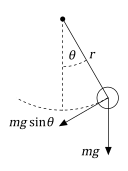

**Derivation of the Equation of Motion**

The pendulum is a simple mechanical system that follows a differential equation. The pendulum is initially at rest in a vertical position. When the pendulum is displaced by an angle $\theta$ and released, the force of gravity pulls it back towards its resting position. Its momentum causes it to overshoot and come to an angle $-\theta$ (if there are no frictional forces), and so on. The restoring force along the motion of the pendulum due to gravity is $-mg\sin\theta$. Thus, according to Newton's second law, the mass times the acceleration must equal $-mg\sin\theta$:

syms m a g theta(t)
Equation = m*a == -m*g*sin(theta)

For a pendulum with length $r$, the acceleration of the pendulum bob is equal to the angular acceleration times $r$.

$a=r\frac{d^2\theta}{dt^2}$.

Substitute for $a$ by using `subs:`

syms r
Equation = subs(Equation, a, r*diff(theta,2))

Isolate the angular acceleration in `Equation` by using `isolate:`

Equation = isolate(Equation, diff(theta, 2))

Collect the constants $g$ and $r$ into a single parameter, which is also known as the natural frequency:

$\omega_0 =\sqrt{\frac{\;g}{r}}$.

syms omega_0
Equation = subs(Equation, g/r, omega_0^2)

**Linearization of the Equation of Motion**

The equation of motion is nonlinear, so it is difficult to solve analytically. Assume the angles are small and linearize the equation by using the Taylor expansion of $\sin\theta$:

syms x
ApproxSin = taylor(sin(x), x, Order = 2)
ApproxSin = subs(ApproxSin, x, theta(t))

The equation of motion becomes a linear equation.

LinearEquation = subs(Equation, sin(theta), ApproxSin)

**Solving Equation of Motion Analytically**

Solve the equation `LinearEquation` by using `dsolve`. Specify initial conditions as the second argument. Simplify the solution by assuming $\omega_0$ is real using `assume`:

syms theta_0 theta_t0
theta_t = diff(theta);
Conditions = [theta(0) == theta_0, theta_t(0) == theta_t0];
assume(omega_0, 'real')
ThetaSolution(t) = dsolve(LinearEquation, Conditions)

**Physical Significance of **$\omega_0$

The term $\omega_0 t$ is called the phase. The cosine and sine functions repeat every $2\pi$. The time needed to change $\omega_0 t$ by $2\pi$ is called the time period:


$$T = \frac{2\pi}{\omega_0} = 2\pi\sqrt{\frac{r}{g}}$$


The time period $T$ is proportional to the square root of the length of the pendulum and it does not depend on the mass. For linear equation of motion, the time period does not depend on the initial conditions.

**Plotting of Pendulum Motion**

Plot the motion of the pendulum for small-angle approximation. Define the physical parameters:

- Gravitational acceleration $g = 9.81\; \textrm{m/s}^2$

- Length of pendulum $r = 1\;\textrm{m}$

gValue = 9.81;
rValue = 1;
omega_0Value = sqrt(gValue/rValue);
T = 2*pi/omega_0Value;

Set initial conditions:

theta_0Value  = 0.1*pi; % Solution only valid for small angles.
theta_t0Value = 0;      % Initially at rest.

Substitute the physical parameters and initial conditions into the general solution:

Vars = [omega_0, theta_0, theta_t0]
Values = [omega_0Value, theta_0Value, theta_t0Value]
ThetaSolutionPlot = subs(ThetaSolution, Vars, Values)

Plot the harmonic pendulum motion:

fplot(ThetaSolutionPlot(t*T)/pi, [0 5]);
grid on;
title('Harmonic Pendulum Motion');
xlabel('t/T'); ylabel('\theta/\pi');

After finding the solution for $\theta(t)$, visualize the motion of the pendulum:

xPosition = sin(ThetaSolutionPlot);
yPosition = -cos(ThetaSolutionPlot);
fanimator(@fplot, xPosition, yPosition, 'ko', ...
    MarkerFaceColor = 'k', AnimationRange = [0 5*T]);
hold on
fanimator(@(t) plot([0 xPosition(t)], [0 yPosition(t)], 'k-'), ...
    AnimationRange = [0, 5*T]);
fanimator(@(t) text(-0.3, 0.3, "Timer: " + num2str(t, 2) + " s"), ...
    AnimationRange = [0, 5*T]);
playAnimation
hold off

Enter the command `playAnimation` to play the animation of the pendulum motion.